## Load measured data

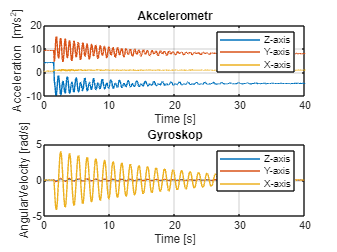

clear all
load data_28_11_2022\data_imu_kyvadlo_dynamic7.mat
sample_rate=200;    
tt=(0:5:5*(size(dataAcc,1)-1))'/1000;
subplot(2,1,1);
plot(tt,dataAcc);grid;title('Akcelerometr');legend('Z-axis','Y-axis','X-axis');xlabel('Time [s]');ylabel('Acceleration [m/s^2]');
subplot(2,1,2);
plot(tt,dataGyro);grid;title('Gyroskop');legend('Z-axis','Y-axis','X-axis');xlabel('Time [s]');ylabel('AngularVelocity [rad/s]');

gyroSignal = (dataGyro(301:end,3));


## Read damping & freq

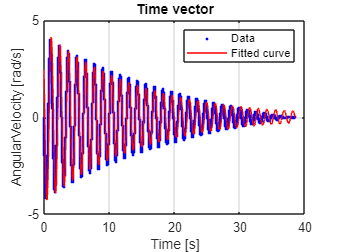

time_vector=(0:5:5*length(gyroSignal)-1)'/1000;
[fitresult, gof] = createFit(time_vector, gyroSignal);


omega=fitresult.w

omega = 4.7510

frek=omega/(2*pi)

frek = 0.7562

b_r=fitresult.b

b_r = 0.0148

## FFT (kontrola frekvence)

Y=fft(gyroSignal);
L=length(Y);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
f = sample_rate*(0:(L/2))/L;
% plot(f,P1)
[m,inx]=max(P1);
frek2=f(inx)

frek2 = 0.7532

omega2=2*pi*frek2

omega2 = 4.7328

## Predpis trajektorie

omb = 2*pi*frek;
om = omb/sqrt(1-b_r^2);
phi0 = asin(147/180);
A=phi0;B=(b_r*om*phi0)/omb;
phi_math=exp(-b_r*om*time_vector).*(A*cos(omb*time_vector)+B*sin(omb*time_vector));


## Kalman

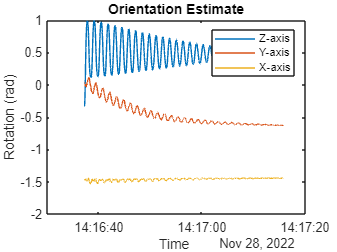

fusion_decimation_factor=1;
filter = imufilter('SampleRate',sample_rate,'DecimationFactor',fusion_decimation_factor,'OrientationFormat','Rotation matrix');
filter.AccelerometerNoise=1e-3;
filter.GyroscopeNoise=1e-2;

rot_matrices = filter(dataAcc(301:end,:),dataGyro(301:end,:));

timesAfterFuse=dataTimestamps(301:fusion_decimation_factor:end);
plot(timesAfterFuse,rotm2eul(rot_matrices))
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis') 
xlabel('Time ')
ylabel('Rotation (rad)')

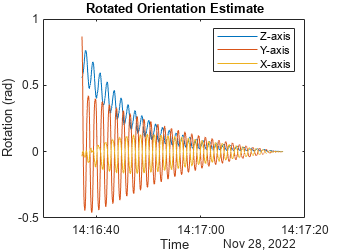

% draw_3D_poseplot(rot_matrices);

R = rot_matrices(:,:,end)';
for i = 1:size(rot_matrices,3)
    rot_matrices_rot(:,:,i)=R*rot_matrices(:,:,i);
end
figure
plot(timesAfterFuse,rotm2eul(rot_matrices_rot))
title('Rotated Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time')
ylabel('Rotation (rad)')

% draw_3D_poseplot(rot_matrices_rot); %uncomment to see 3D pose plot

## Porovnání orientací

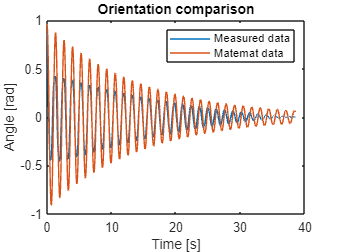

eul=rotm2eul(rot_matrices_rot);
phi_kalman=eul(:,2);
figure;
plot(time_vector,phi_kalman);
hold on
plot(time_vector,phi_math);xlabel('Time [s]');ylabel('Angle [rad]');legend('Measured data','Matemat data');title('Orientation comparison');
hold off

## Kalibrace

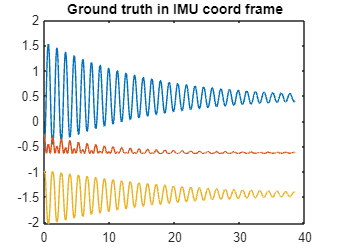

Accelerometer=dataAcc(301:end,:);
Gyroscope=dataGyro(301:end,:);
sensorData=table(Accelerometer,Gyroscope);

truth_rot=eul2rotm([zeros(length(phi_math),1) phi_math zeros(length(phi_math),1)]);
for i = 1:size(truth_rot,3)
    truth_rot(:,:,i)=R'*truth_rot(:,:,i);
end

figure;plot(time_vector,rotm2eul(truth_rot));title('Ground truth in IMU coord frame');

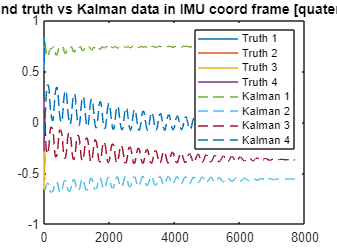


figure;plot(time_vector,rotm2quat(truth_rot));hold on;plot(rotm2quat(rot_matrices),'--');hold off; title('Ground truth vs Kalman data in IMU coord frame [quaternions]');legend('Truth 1','Truth 2','Truth 3','Truth 4','Kalman 1','Kalman 2','Kalman 3','Kalman 4');


Orientation=quaternion(rotm2quat(truth_rot));
groundTruthTraj = table(Orientation);

reset(filter)
config=tunerconfig("imufilter","MaxIterations",20,"ObjectiveLimit",0.001,"StepForward",2);
config.TunableParameters = setdiff(config.TunableParameters,{'GyroscopeNoise', 'AccelerometerNoise'});
tune(filter,sensorData,groundTruthTraj,config)

    Iteration    Parameter                        Metric
    _________    _________                        ______
    1            GyroscopeDriftNoise              2.9254
    1            LinearAccelerationDecayFactor    2.9247
    1            LinearAccelerationNoise          2.9243
    2            GyroscopeDriftNoise              2.9243
    2            LinearAccelerationDecayFactor    2.9233
    2            LinearAccelerationNoise          2.9225
    3            GyroscopeDriftNoise              2.9225
    3            LinearAccelerationDecayFactor    2.9214
    3            LinearAccelerationNoise          2.9198
    4            GyroscopeDriftNoise              2.9198
    4            LinearAccelerationDecayFactor    2.9191
    4            LinearAccelerationNoise          2.9151
    5            GyroscopeDriftNoise              2.9151
    5            LinearAccelerationDecayFactor    2.9149
    5            LinearAccelerationNoise          2.90

## Použití nakalibrovaného filtru

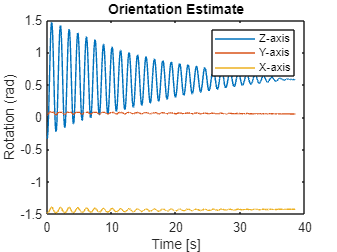

rot_matrices_calibrated = filter(dataAcc(301:end,:),dataGyro(301:end,:));

timesAfterFuse=dataTimestamps(301:fusion_decimation_factor:end);
plot(time_vector,rotm2eul(rot_matrices_calibrated))
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis') 
xlabel('Time [s]')
ylabel('Rotation (rad)')

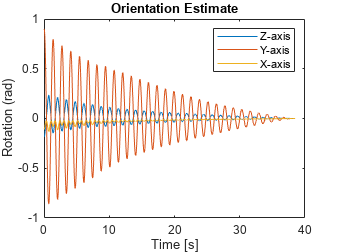

% draw_3D_poseplot(rot_matrices_calibrated);

RR = rot_matrices_calibrated(:,:,end)';
for i = 1:size(rot_matrices_calibrated,3)
    rot_matrices_calibrated_rot(:,:,i)=RR*rot_matrices_calibrated(:,:,i);
end
figure
plot(time_vector,rotm2eul(rot_matrices_calibrated_rot))
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time [s]')
ylabel('Rotation (rad)')

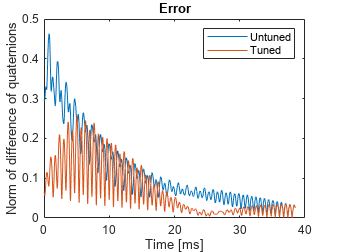

% draw_3D_poseplot(rot_matrices_calibrated_rot);

figure;
plotPerformance(rot_matrices_rot,[zeros(length(phi_math),1) phi_math zeros(length(phi_math),1)]);hold on;
plotPerformance(rot_matrices_calibrated_rot,[zeros(length(phi_math),1) phi_math zeros(length(phi_math),1)]);legend('Untuned','Tuned');title('Error');xlabel('Time [s]');ylabel(['Norm of difference of quaternions' ...
    '']);hold off;